# 4.5 Integral Controllers

## Example 4.5: Continuous Control via the Controller Canonical Form


$$\begin{array}{l}
\dot{\mathbf{x}} =\left\lbrack \begin{array}{ccc}
-0\ldotp 14 & 0\ldotp 33 & -0\ldotp 33\\
0\ldotp 1 & -0\ldotp 28 & 0\\
0 & 1\ldotp 7 & -0\ldotp 77
\end{array}\right\rbrack \mathbf{x}+\left\lbrack \begin{array}{c}
0\\
0\\
-0\ldotp 025
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{ccc}
2 & 0 & 0
\end{array}\right\rbrack \mathbf{x}
\end{array}$$


A = [-0.14 0.33 -0.33;0.1 -0.28 0;0 1.7 -0.77];
B = [0 0 -0.025]';
C = [2 0 0];
D = 0;

damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.46e-01 + 2.16e-01i     5.60e-01       2.60e-01          6.86e+00    
 -1.46e-01 - 2.16e-01i     5.60e-01       2.60e-01          6.86e+00    
 -8.99e-01                 1.00e+00       8.99e-01          1.11e+00    




E = eig(A);
tau = -1./E(imag(E)==0)

tau =        1.1129


wn = abs(E(imag(E)>0))

wn =       0.26028


zeta = -real(E(imag(E)>0))./wn

zeta =        0.5598



l_cl = [-0.67 -0.67 -0.67]'

l_cl =         -0.67
        -0.67
        -0.67


chP_a = poly(E);
a = chP_a(end:-1:2);
chP_alph = poly(l_cl);
alpha = chP_alph(end:-1:2);
K_cc = alpha-a;

sz = size(B,1);
P = zeros(sz)

P =      0     0     0
     0     0     0
     0     0     0


for i = 1:sz
    if i == 1
        P(:,sz) = B;
    else
        P(:,sz-i+1) = A*P(:,sz-i+2)+chP_a(i)*P(:,sz);
    end
end

K = K_cc/P;
eig(A-B*K)

ans =         -0.67 +          0i
        -0.67 + 8.8882e-07i
        -0.67 - 8.8882e-07i



sys_ss = ss(A-B*K,B,C,D);
sys_tf = tf(sys_ss)


sys_tf =
 
         0.0165 s + 0.00462
  ---------------------------------
  s^3 + 2.01 s^2 + 1.347 s + 0.3008
 
Continuous-time transfer function.



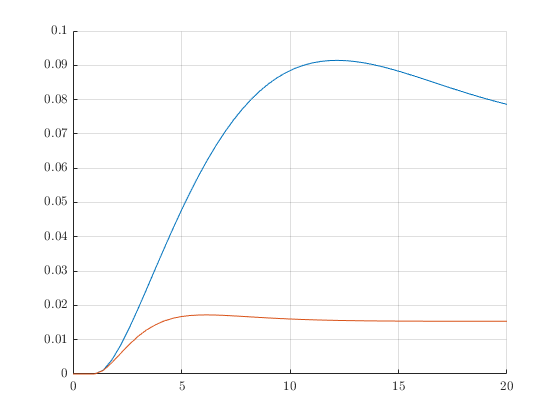


simSwitch = -1;
sim('Int_control_ex_OL.slx',20)
sim('Int_control_ex_CL.slx',20)
figure, hold on, grid on
plot(t_OL, y_OL.signals.values)
plot(t_CL, y_CL.signals.values)

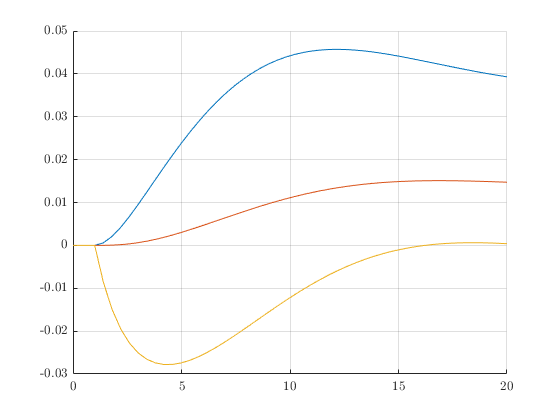

figure, hold on, grid on
plot(t_OL, x_OL.signals.values)

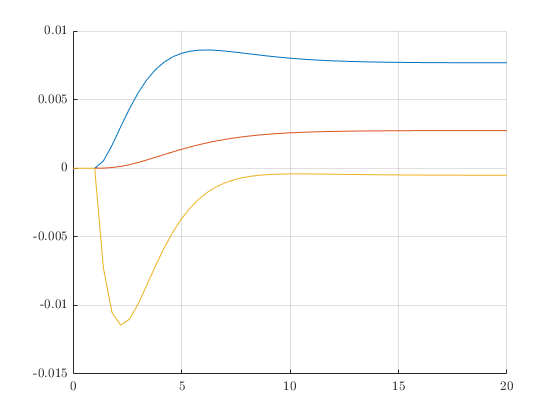

figure, hold on, grid on
plot(t_CL, x_CL.signals.values)

## Example 4.6 Discrete Control via the Controller Canonical Form

tau/5

ans =       0.22257


Ts = 0.2;
F = expm(A*Ts)

F =       0.97295     0.052931    -0.060311
     0.019182       0.9461  -0.00060995
    0.0031422       0.3063       0.8572


syms t
sys_d = c2d(sys_ss,Ts);
G = sys_d.B

G =    0.00014709
   9.9516e-07
   -0.0042638


l_cld = exp(l_cl*Ts)

l_cld =       0.87459
      0.87459
      0.87459


K_d = acker(A,B,l_cld)

K_d =        432.35      -2066.6       152.55


eig(F-G*K)

ans =       0.86123 +          0i
      0.88156 +    0.02052i
      0.88156 -    0.02052i


## Example 4.12 Itegral Control of a Third Order System


$$\begin{array}{l}
\dot{{\mathbf{x}}_a } =\left\lbrack \begin{array}{c}
\dot{\mathbf{x}} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-0\ldotp 14 & 0\ldotp 33 & -0\ldotp 33 & 0\\
0\ldotp 1 & -0\ldotp 28 & 0 & 0\\
0 & 1\ldotp 7 & -0\ldotp 77 & 0\\
-2 & 0 & 0 & 0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-0\ldotp 025\\
0
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1
\end{array}\right\rbrack r\\
y=\left\lbrack \begin{array}{cccc}
2 & 0 & 0 & 0
\end{array}\right\rbrack {\mathbf{x}}_a 
\end{array}$$



$$\begin{array}{l}
\dot{{\mathbf{x}}_a } =\left\lbrack \begin{array}{c}
\dot{\mathbf{x}} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathbf{A} & 0\\
-\mathbf{C} & 0
\end{array}\right\rbrack {\mathbf{x}}_a +\left\lbrack \begin{array}{c}
\mathbf{B}\\
0
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
0\\
{\mathbf{I}}_r 
\end{array}\right\rbrack r\\
y=\left\lbrack \begin{array}{cc}
\mathbf{C} & 0
\end{array}\right\rbrack {\mathbf{x}}_a 
\end{array}$$


A1 = [A [0 0 0]';-C 0]

A1 =         -0.14         0.33        -0.33            0
          0.1        -0.28            0            0
            0          1.7        -0.77            0
           -2            0            0            0


B1 = [B;0];
Br = [0 0 0 1]';
C1 = [C 0];
D1 = 0;
l_cl = [-0.67 -0.67 -0.67 -0.67]';

K_ = acker(A1,B1,l_cl);
K1 = K_(1:end-1)

K1 =        210.67      -88.949        -59.6


Ki = -K_(end)

Ki =        43.617


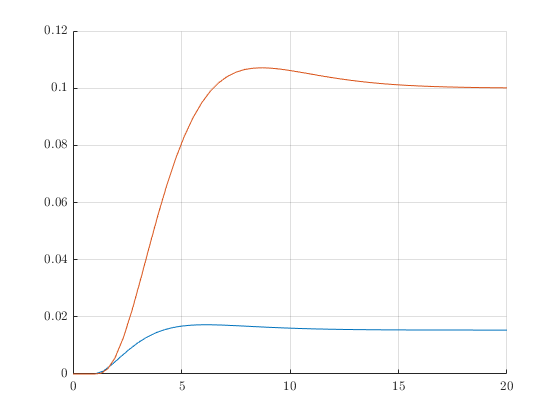

sim('Int_control_ex_CLI',20)
figure, hold on, grid on
plot(t_CL, y_CL.signals.values)
plot(t_CLI, y_CLI.signals.values)

figure, hold on, grid on
plot(t_CL, x_CL.signals.values)

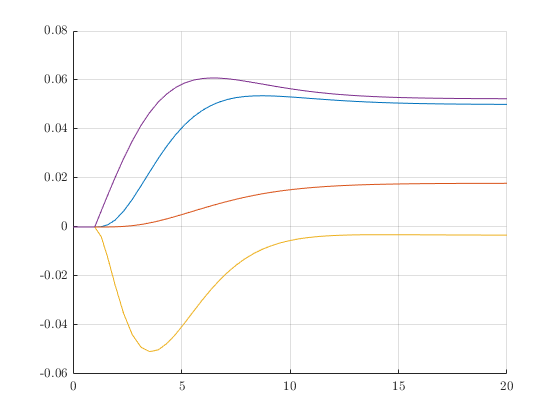

figure, hold on, grid on
plot(t_CLI, x_CLI.signals(2).values)
plot(t_CLI, x_CLI.signals(1).values/200)

## Example 4.17 Discrete (Predictive) Observer for a SISO system

Ts = 0.2;
l_co = [-5 -3.5+3.5j -3.5-3.5j]';
l_do = exp(Ts*l_co);
p = poly(l_do);

sys_d = c2d(ss(A,B,C,D),Ts)


sys_d =
 
  A = 
               x1          x2          x3
   x1       0.973     0.05293    -0.06031
   x2     0.01918      0.9461  -0.0006099
   x3    0.003142      0.3063      0.8572
 
  B = 
              u1
   x1  0.0001554
   x2  1.037e-06
   x3  -0.004634
 
  C = 
       x1  x2  x3
   y1   2   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.



F = sys_d.A

F =       0.97295     0.052931    -0.060311
     0.019182       0.9461  -0.00060995
    0.0031422       0.3063       0.8572


G = sys_d.B

G =    0.00015539
   1.0369e-06
   -0.0046339


chP_Fl = polyvalm(p,F)

chP_Fl =       0.27592     0.029101    -0.059077
     0.021581      0.24571   -0.0024773
     0.012762      0.28647      0.16066


% 
% F_a = charpoly(F)
% Q = zeros(size(F));
% sz = size(F,1);
% for i = 1:3
%     for j = 1:i
%         Q(sz+1-i,:)=Q(sz+1-i,:)+C*F^(i-j)*F_a(j);
%     end
% end

Mo = [C;C*F;C*F^2]

Mo =             2            0            0
       1.9459      0.10586     -0.12062
       1.8949      0.16621     -0.22082



% alph_o = p(end:-1:2);
% L_oc = (alph_o-a)'
L = chP_Fl/Mo*[0 0 1]'

L =       0.82438
      -8.8262
      -15.492


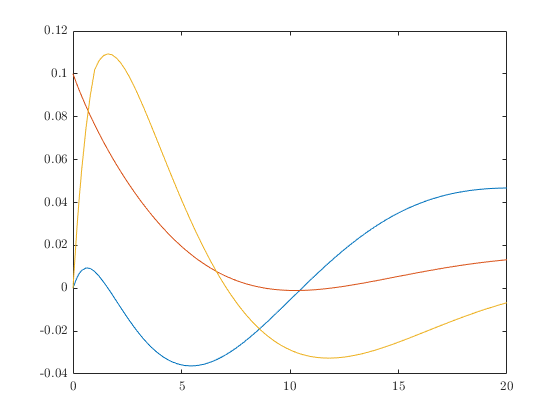

sim('Obs_ex_do',20)
figure
plot(t_do,x_do.signals(1).values)

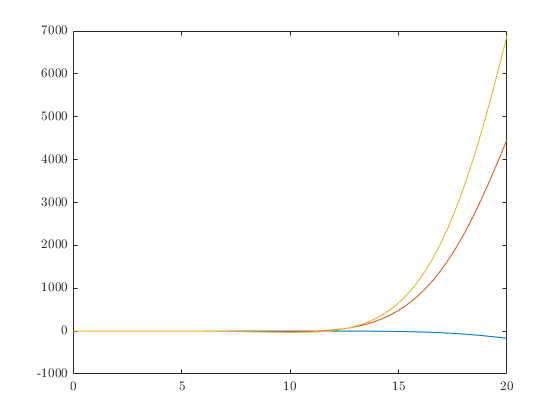

figure
plot(t_do,x_do.signals(2).values)

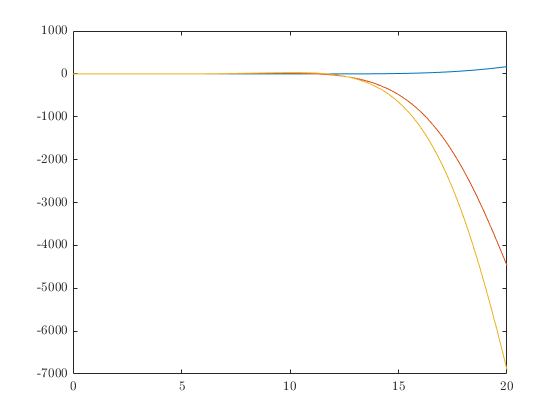

figure
plot(t_do,(x_do.signals(1).values-x_do.signals(2).values))